FTBO

La fréquence de transition est un peu plus élevée que ce qu'on désirait

R = 1

R = 1

Km = 1/R

Km = 1

Khach = 48 

Khach = 48

Kcourant = 0.10416

Kcourant = 0.1042

Kf = 1.79

Kf = 1.7900

K = Km*Khach*Kcourant*Kf %Gain global

K = 8.9494

ft = 250 

ft = 250

%ft désirée, en FTBO on obtient ft=650Hz
%si on met ft=300 on a ft sur le bode FTBO à 500?
%quand on met ft=250, sur le bode en FTBO on obtient ft=400Hz. Cela est du
%au fait qu'on a calculé notre FTBO avec des simplifications?

fm=80

fm = 80

tau_m = 1/(2*pi*fm)

tau_m = 0.0020


ff=2000

ff = 2000

tau_f = 1/(2*pi*ff)

tau_f = 7.9577e-05


tau_i = K/(2*pi*ft) 

tau_i = 0.0057

fi = 1/(2*pi*tau_i)

fi = 27.9347

tau_c = tau_m

tau_c = 0.0020


Gm=tf([Km], [tau_m 1])

Gm =
 
        1
  --------------
  0.001989 s + 1
 
Continuous-time transfer function.



F=tf([Kf], [tau_f 1])

F =
 
       1.79
  ---------------
  7.958e-05 s + 1
 
Continuous-time transfer function.



C=tf([tau_c 1],[tau_i 0])

C =
 
  0.001989 s + 1
  --------------
    0.005697 s
 
Continuous-time transfer function.




G=K*Gm*F*C

G =
 
              0.03187 s + 16.02
  -----------------------------------------
  9.02e-10 s^3 + 1.179e-05 s^2 + 0.005697 s
 
Continuous-time transfer function.



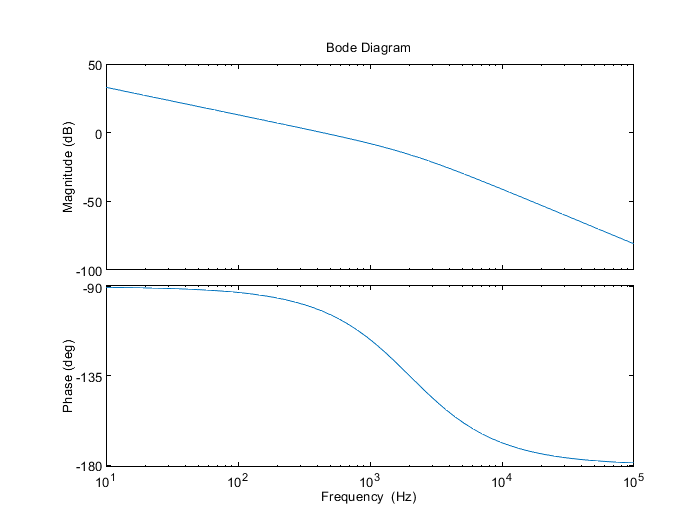

options = bodeoptions;
options.FreqUnits = 'Hz' ; %par defaut en rad/s
bode(G, options)

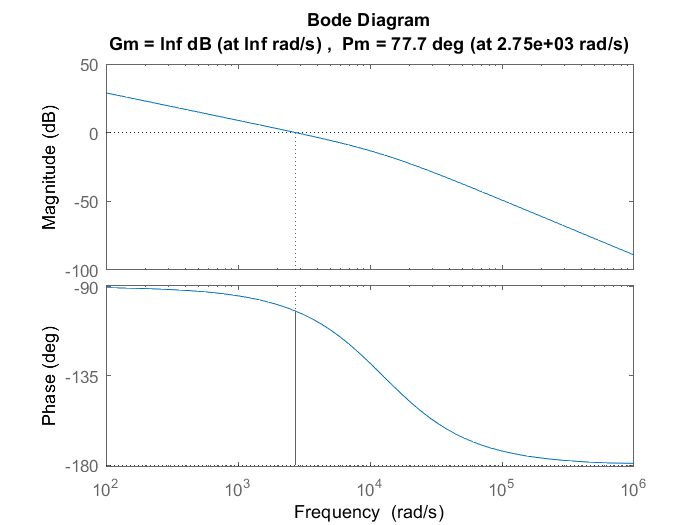

margin(G)


sim("trottinette.slx")

ans =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [56x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


simout = out.simout

  timeseries

  Common Properties:
            Name: ''
            Time: [71x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [71x1 double]
        DataInfo: 

FTBF

On a une grande marge de phase, permettant à notre systeme d'avoir une reponse à un echelon sans resonance/depassement. 

Pour changer la frequence de coupure en BF il faut modifier le tau_i afin de shifter la courbe et donc la frequence de transition.

FTBF = G/(1+G)

FTBF =
 
                 2.875e-11 s^4 + 3.901e-07 s^3 + 0.0003704 s^2 + 0.09127 s
  ----------------------------------------------------------------------------------------
  8.136e-19 s^6 + 2.126e-14 s^5 + 1.78e-10 s^4 + 5.244e-07 s^3 + 0.0004029 s^2 + 0.09127 s
 
Continuous-time transfer function.



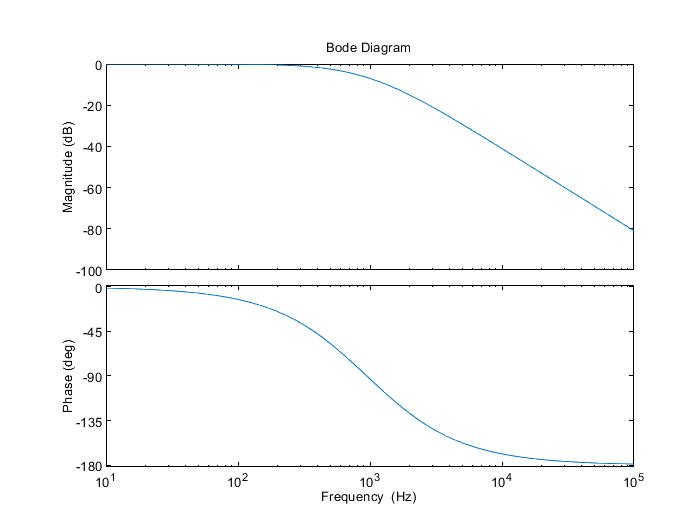

bode(FTBF, options) %ft à 1kHz, décalage du au fait de fermer la boucle

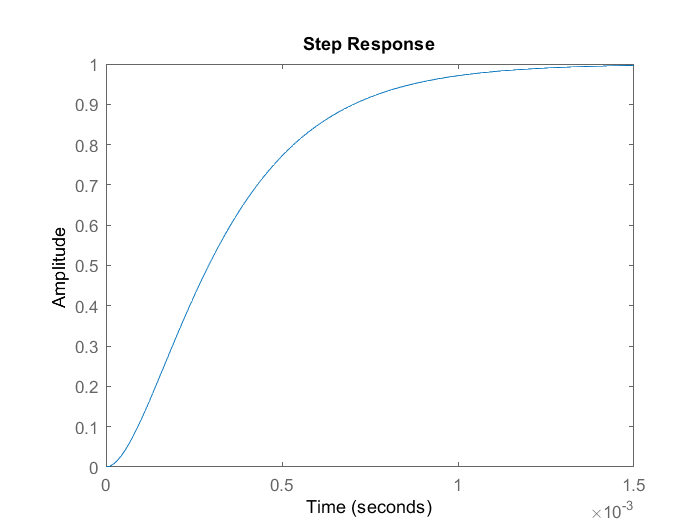

step(FTBF, 1.5e-3)

response_info = stepinfo(FTBF)

response_info = struct with fields:
        RiseTime: 6.1311e-04
    SettlingTime: 0.0011
     SettlingMin: 0.9006
     SettlingMax: 0.9991
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9991
        PeakTime: 0.0018


Saturateur

On ajoute un saturateur entre le correcteur C(p) et Gm(p) pour que alpha ne dépasse pas ±0.5

sim("trottinette_v2.slx")

ans =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [57x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


simout = out.simout

  timeseries

  Common Properties:
            Name: ''
            Time: [71x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [71x1 double]
        DataInfo: 

Passage au discret 

Calcul theorique de C(z)!

Avantages/inconvenients d'avoir Te petit/grand: 

De C(p) à C(z)

On va vérifier la transformée en z du bloc correcteur C

Te = 1/400 %valeur exacte de fmax/fresonance à chercher, presque egale à ft

Te = 0.0025

methode =  'tustin'

methode = 'tustin'

C_z = c2d(C,Te,methode) 

C_z =
 
  0.5686 z - 0.1298
  -----------------
        z - 1
 
Sample time: 0.0025 seconds
Discrete-time transfer function.



On a un problème avec le correcteur en discret, la reponse temporelle de trottinette_discret_v3 n'est pas comme prévue

sim("trottinette_discret_v3.slx")

ans =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [71x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


simout = out.simout

  timeseries

  Common Properties:
            Name: ''
            Time: [71x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [71x1 double]
        DataInfo: 